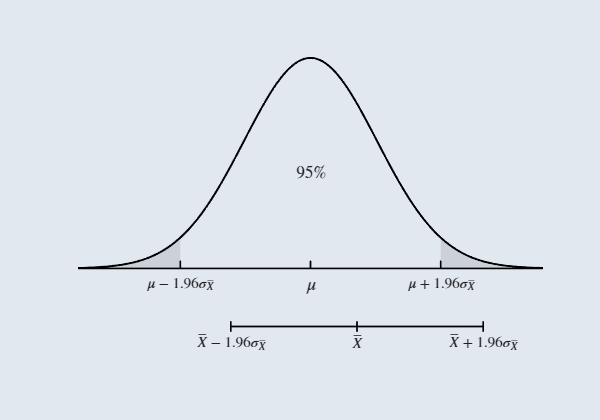

clear
clc

% Parámetros de la distribución normal estándar
mu = 0;
sigma = 1;
x = linspace(-3.5, 3.5, 500);
y = normpdf(x, mu, sigma);

% Color de fondo personalizado
color_fondo = [226 232 240] / 255;

% Configuración de figura y dimensiones
fig = figure('Color', color_fondo);
set(gcf, 'Units', 'inches', 'Position', [0 0 5 3.5]);

hold on;

% Sombreado de colas (regiones fuera del 95%)
x_izq = linspace(-3.5, -1.96, 100);
y_izq = normpdf(x_izq, mu, sigma);
fill([x_izq, -1.96, -3.5], [y_izq, 0, 0], [0.8 0.82 0.85], 'EdgeColor', 'none');

x_der = linspace(1.96, 3.5, 100);
y_der = normpdf(x_der, mu, sigma);
fill([1.96, x_der, 3.5], [0, y_der, 0], [0.8 0.82 0.85], 'EdgeColor', 'none');

% Curva principal y eje horizontal
plot(x, y, 'k-', 'LineWidth', 1.2);
line([-3.5, 3.5], [0, 0], 'Color', 'k', 'LineWidth', 1);

% Marcas sobre la distribución
plot([0, 0], [0, 0.015], 'k-', 'LineWidth', 1);
plot([-1.96, -1.96], [0, 0.015], 'k-', 'LineWidth', 1);
plot([1.96, 1.96], [0, 0.015], 'k-', 'LineWidth', 1);

x_bar = 0.7;
%plot([x_bar, x_bar], [0, 0.015], 'k-', 'LineWidth', 1);

% Etiquetas matemáticas
text(0, -0.03, '$\mu$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 11);
text(-1.96, -0.03, '$\mu - 1.96\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);
text(1.96, -0.03, '$\mu + 1.96\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);
%text(x_bar, -0.03, '$\bar{X}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);

% Cota e intervalo del 95%
%annotation('doublearrow', [0.33, 0.70], [0.57, 0.57]);
text(0, 3*0.06, '95\%', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'BackgroundColor', color_fondo, 'FontSize', 10);

% Intervalo muestral inferior
y_shift = -0.11;
plot([-1.2, 2.6], [y_shift, y_shift], 'k-', 'LineWidth', 1);
plot([-1.2, -1.2], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);
%plot([0, 0], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);
plot([x_bar, x_bar], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);
plot([2.6, 2.6], [y_shift - 0.01, y_shift + 0.01], 'k-', 'LineWidth', 1);

text(-1.2, y_shift - 0.03, '$\bar{X} - 1.96\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);
text(2.6, y_shift - 0.03, '$\bar{X} + 1.96\sigma_{\bar{X}}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);
text(x_bar, y_shift - 0.03, '$\bar{X}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center', 'FontSize', 9);


% Formato de ejes
ylim([-0.20, 0.45]);
xlim([-3.5, 3.5]);
axis off;
hold off;

% Exportación idéntica a tu formato
set(gcf, 'Units', 'inches', 'Position', [0 0 5 3.5]);
exportgraphics(gcf, 'distribucion_normal_fondo.png', 'Resolution', 300);
exportgraphics(gcf, 'distribucion_normal_fondo.svg', 'ContentType', 'vector');